## Parametri di input

NetOption = "LSTM";    % tipologia di rete utilizzata
ratio = 0.8;% porzione di dati da utilizzare per il training e per il test
MiniBatchSize =256 ;%MiniBatchSize
MaxEpochs = 100;%epoche massime
learningrate = 0.0002;%Learning rate
solver = "adam";% solver option

## Impostazioni iniziali

%parametri per il preprocessamento
anno=1995;%anno fino al quale considerare i dati (max 2000)
flag.channel_3=1; %0=oreografia/ 1=batimetria/2=set_traversia
flag.casual=0;%randomizza i dati di test e train
flag.WaveletTrasf=0; %applica la trasf-wavelet(1)
flag.dim_immagine=0 % (1)immagini [32 44 3],(0) immagini [5 5 3] (ATT:utilizzabile solo con net: LSTM)

flag = struct with fields:
       channel_3: 1
          casual: 0
    WaveletTrasf: 0
    dim_immagine: 0


flag.growing=0;%(1)applica la tecnica del growing al dataset di train; (0)non applica la tecnica
flag.save_net=1;%(1)salva le informazioni sulla rete (200-300 MB); (0) non le salva (qualche KB)
replica=20;%replica i picchi n volte(utilizzato per tecnica del growing)
%----------
%divisione dei dati
Validation_size=0.2; %porzione dei dati di train da dedicare alla validation
%---------
%dati riferiti alla rete
numResponses = 1;%numero d'uscite
FiltZise = [5 5];%dimensione filtri 
num_filtri=32;%numero di filtri
flag.piu_prove=1;%(1)esegue 10 prove con rng variabile;(0)esegue una prova
%------------------
%parametri riferiti al calcolo dei picchi
Window_peaks=6;%finistra di n campioni
MinPeaksDistance=12;%distanza minima di rilevazione dei picchi

%-------------------
if flag.piu_prove==1
end_prove=10;
else
end_prove=1;
end
%scegliamo la dimensione degli ingressi
if flag.dim_immagine==1
imageSize=[32 44 3];
indici_imm.start_riga=1;
indici_imm.end_riga=32;
indici_imm.start_colonna=1;
indici_imm.end_colonna=44;
else
imageSize=[5 5 3];
indici_imm.start_riga=12;
indici_imm.end_riga=16;
indici_imm.start_colonna=21;
indici_imm.end_colonna=25;
end

data1 = load("Dataset_sincronizzato.mat");

[riga1 colonna1]=size(data1.time);
j=1;
[date.Yi,date.Mi,date.Di,date.Hi,date.MNi] = datevec(data1.time);

%seleziono fino a che anno considerare

%ricavo l'indice al quale fermarci

for i=1:riga1
    if date.Yi(i)<=anno
     data.time(j)=data1.time(i);   
     data.Vento(:,:,:,j)=data1.Vento(:,:,:,i);
     data.Hs(j)=data1.Hs(i);
     data.Tp(j)=data1.Tp(i);
     data.Dir(j)=data1.Dir(i);
     j=j+1;
    end
end
data.time=data.time';
data.Hs=data.Hs';
data.Tp=data.Tp';

[riga colonna]=size(data.time);
%taglio i dati con Hs>4
for i=1:riga
    if data.Hs(i)<0
     data.time(i)=data.time(i);   
     data.Vento(:,:,:,i)=data.Vento(:,:,:,i);
     data.Hs(i)=0;
     data.Tp(i)=data.Tp(i);
     data.Dir(i)=data.Dir(i);
     end
end
clearvars('data1')


if flag.channel_3==1 
load("Oreografia.mat")
for i=1:riga
data.Vento(:,:,3,i)=batimetria/1000; %considero le altezze in km;
end
elseif flag.channel_3==2
load("Oreografia.mat")
for i=1:riga
data.Vento(:,:,3,i)=set_traversia; %considero le altezze in km;
end

end

%------------

% data visualization
figure
plot(datetime(datestr(data.time)),data.Hs,'.','LineWidth',0.25);
ylabel("Altezza d'onda significativa Hs(m)");
xlabel("Tempo");
xlim([datetime(1989,07,1) datetime(1995,12,25)]);
set(gca,'FontSize',24)
title("Altezza significativa(Hs) dal 1989 al 1995(passo 1 ora)")
set(gca,'FontSize',24,'FontName','Adobe Kaiti Std R','FontWeight','bold');
set(gca, 'Box', 'on', 'LineWidth', 1, 'Layer', 'top',...
    'XMinorTick', 'on', 'YMinorTick', 'on', 'XGrid', 'on', 'YGrid', 'on', ...
    'TickDir', 'in', 'TickLength', [.015 .015],...
    'FontName', 'avantgarde', 'FontSize', 12, 'FontWeight', 'normal');

## **DIVISIONE DEL DATASET TRA TEST E TRAIN**

numStepsTraining = round(ratio*numel(data.Hs));
index=randperm(size(data.Hs,1),size(data.Hs,1));

indexTrain = 1:numStepsTraining;

if flag.casual==1% randomizza i dati
indexTrain=index(indexTrain);
end

%Train data
TrainX = data.Vento(:,:,:,indexTrain);
TrainY(:,1)=data.Hs(indexTrain);
TrainY(:,2)=data.Dir(indexTrain);
indexTest = numStepsTraining+1:size(data.Hs);
if flag.casual==1
indexTest = index(indexTest);
end

% Testing data
TestX = data.Vento(:,:,:,indexTest);
TestY=data.Hs(indexTest);
TestY(:,2)=data.Dir(indexTest);


if flag.WaveletTrasf==1 %trasformata non utilizzata all'interno della tesi
[Out.ca,Out.cd] = lwt(TrainY(:,1),'Level',1);
[Out1.ca,Out1.cd] = lwt(Out.ca,'Level',1);
[Out_T.ca,Out_T.cd] = lwt(TestY(:,1),'Level',1);
[Out1_T.ca,Out1_T.cd] = lwt(Out.ca,'Level',1);


%[IN.appr,IN.or,IN.vert,IN.dia] = lwt2(TrainX,'Level',1);
%[IN1.appr,IN1.or,IN1.vert,IN1.dia] = lwt2(IN.appr,'Level',1);
%[IN_T.appr,IN_T.or,IN_T.vert,IN_T.dia] = lwt2(TestX,'Level',1);
%[IN1_T.appr,IN1_T.or,IN1_T.vert,IN1_T.dia] = lwt2(IN_T.appr,'Level',1);

end

%Validation Data
idx=1:round(length(TrainY(:,1))*Validation_size);  

ValidationX = TrainX(:,:,:,idx);
TrainX(:,:,:,idx) = [];

ValidationY = TrainY(idx,1);
ValidationY(:,2) = TrainY(idx,2);

TrainY(idx,:) = [];
indexTrain(idx) = [];

TrainY_originale=TrainY;


## **Utiizzo della tecnica di growing sul dataset di TRAIN**

H0=mean(TestY(:,1))+3*std(TestY(:,1));%calcola il valore medio di Hs nei dati di test
if flag.growing==1
%creazione del dataset esteso per i picchi
[peak_value_train, peak_location_train] = findpeaks(TrainY(:,1),'MinPeakHeight',H0,'MinPeakDistance',12);

j=1;
a=1;
for i=1:size(peak_location_train,1)
    for j= peak_location_train(i)-6:peak_location_train(i)+3
      picchi_esteso(a) = j;
      a=a+1;
    end
end
%replica i picchi trovati all'interno del dataset di train
for i=1:replica
limite_dataset=length(TrainY(:,1));
    for i=limite_dataset+1:limite_dataset+length(picchi_esteso)
        TrainX(:,:,:,i)=TrainX(:,:,:,picchi_esteso(i-limite_dataset));
        TrainY(i,1)=TrainY(picchi_esteso(i-limite_dataset));
    end
end

end

## **Definizione dei layer delle reti utilizzate**

numFeatures = size(TrainX);

for ripeti=1:end_prove

    if strcmp(NetOption,"Network2")
    % you can follow this template and create your own Architecture
    rng(ripeti)
   layers = [...
        % Here input the sequence. No need to be modified
        
        imageInputLayer(imageSize)
  
        %sequenceFoldingLayer('Name','fold')
        % from here do your engeneering design of your CNN feature
        % extraction
        convolution2dLayer(FiltZise,num_filtri,'Padding','same','WeightsInitializer','He','Name','conv','DilationFactor',1);%modificato (he)
        batchNormalizationLayer('Name','bn')
        reluLayer('Name','elu') %layer aggiunto
        % eluLayer('Name','elu')
        
              
        convolution2dLayer(FiltZise,num_filtri,'Padding','same','WeightsInitializer','He','Name','conv1','DilationFactor',2); 
        reluLayer('Name','elu1') %layer aggiunto
        %eluLayer('Name','elu1')
        
        convolution2dLayer(FiltZise,num_filtri,'Padding','same','WeightsInitializer','He','Name','conv2','DilationFactor',4);
        reluLayer('Name','elu2') %layer aggiunto
        %eluLayer('Name','elu2')

        convolution2dLayer(FiltZise,num_filtri,'Padding','same','WeightsInitializer','He','Name','conv3','DilationFactor',8);
        reluLayer('Name','elu3') %layer aggiunto
        %eluLayer('Name','elu3')
        convolution2dLayer(FiltZise,num_filtri,'Padding','same','WeightsInitializer','He','Name','conv4','DilationFactor',16);
        reluLayer('Name','elu4') %layer aggiunto
        %eluLayer('Name','elu4')
        
        averagePooling2dLayer(1,'Stride',FiltZise,'Name','pool1')%modificato(filtsize)
      
        % here you finish your CNN design and next step is to unfold and
        % flatten. Keep this part like this
        %sequenceUnfoldingLayer('Name','unfold')
        flattenLayer('Name','flatten')

        % from here the RNN design. Feel free to add or remove layers
        gruLayer(128,'Name','gru1','RecurrentWeightsInitializer','He','InputWeightsInitializer','He')
        lstmLayer(64,'Name','lstm1','RecurrentWeightsInitializer','He','InputWeightsInitializer','He')
        dropoutLayer(0.25,'Name','drop1') %modificato(0.25)
        % this last part you must change the outputmode to last
        lstmLayer(32,'OutputMode',"last",'Name','lstm2','RecurrentWeightsInitializer','He','InputWeightsInitializer','He')%modificato(32)
        dropoutLayer(0.25,'Name','drop2') %modificato(0.25)
        % here finish the RNN design
        % use a fully connected layer with one neuron because you will predict one step ahead
        fullyConnectedLayer(numResponses,'Name','fc')
        regressionLayer('Name','output')];
      
    layers = layerGraph(layers);
    %layers= connectLayers(layers,'fold/miniBatchSize','unfold/miniBatchSize');

elseif strcmp(NetOption,"LSTM")
    rng(ripeti)
    % a simple RNN design
    layers = [...
        imageInputLayer(imageSize)
        % from here the RNN design. Feel free to add or remove layers
        flattenLayer('Name','flatten')
        lstmLayer(50,'Name','lstm1','RecurrentWeightsInitializer','He','InputWeightsInitializer','He')%modificato(64)
        dropoutLayer(0.3,'Name','drop2')
        % this last part you must change the outputmode to last
        
        %-------------
        fullyConnectedLayer(numResponses,'Name','fc')
        regressionLayer('Name','output')];
elseif strcmp(NetOption,"Network1")
    %layers = resnet50(imageSize,numResponses);
    rng(ripeti)
   
      layers=[ 
        imageInputLayer(imageSize)
        % from here do your engeneering design of your CNN feature
        % extraction
        convolution2dLayer(FiltZise,num_filtri,'Padding','same','WeightsInitializer','he','Name','conv','DilationFactor',1);
        batchNormalizationLayer('Name','bn')
        reluLayer('Name','elu')
        dropoutLayer(0.3,'Name','drop1')
        averagePooling2dLayer(20,'Stride',FiltZise,'Name','pool1')
        
        % from here the RNN design. Feel free to add or remove layers
        flattenLayer('Name','flatten')
        lstmLayer(50,'Name','lstm1','RecurrentWeightsInitializer','He','InputWeightsInitializer','He')%modificato(64)
        dropoutLayer(0.3,'Name','drop2')
        % this last part you must change the outputmode to last
        fullyConnectedLayer(numResponses,'Name','fc')
        regressionLayer('Name','output')];

    layers = layerGraph(layers);

    elseif strcmp(NetOption,"Network3")
  
    rng(ripeti)
    layers = [...
        % Here input the sequence. No need to be modified
        
        imageInputLayer(imageSize)
        
        %sequenceFoldingLayer('Name','fold')
        % from here do your engeneering design of your CNN feature
        % extraction
        convolution2dLayer(FiltZise,num_filtri,'Padding','same','WeightsInitializer','he','Name','conv','DilationFactor',1);
        batchNormalizationLayer('Name','bn')
        reluLayer('Name','elu')

        convolution2dLayer(FiltZise,num_filtri,'Padding','same','WeightsInitializer','he','Name','conv1','DilationFactor',2);
        batchNormalizationLayer('Name','bn1')
        reluLayer('Name','elu1')

        dropoutLayer(0.3,'Name','drop1')
        averagePooling2dLayer(2,'Stride',FiltZise,'Name','pool1')
        
        %sequenceUnfoldingLayer('Name','unfold')
        flattenLayer('Name','flatten')

        % from here the RNN design. Feel free to add or remove layers
        bilstmLayer(400,'Name','lstm1','RecurrentWeightsInitializer','He','InputWeightsInitializer','He')
        dropoutLayer(0.3,'Name','drop2')
        % this last part you must change the outputmode to last
        bilstmLayer(200,'OutputMode','last','Name','lstm2','RecurrentWeightsInitializer','He','InputWeightsInitializer','He')
        dropoutLayer(0.3,'Name','drop3')
        bilstmLayer(100,'OutputMode','last','Name','lstm3','RecurrentWeightsInitializer','He','InputWeightsInitializer','He')
        dropoutLayer(0.3,'Name','drop4')
        fullyConnectedLayer(numResponses,'Name','fc')
        regressionLayer('Name','output')];

    layers = layerGraph(layers);
    %layers= connectLayers(layers,'fold/miniBatchSize','unfold/miniBatchSize');
elseif strcmp(NetOption,"Network4")
  
    rng(ripeti)
    layers = [...
        % Here input the sequence. No need to be modified
        
        imageInputLayer(imageSize)
        
        %sequenceFoldingLayer('Name','fold')
        % from here do your engeneering design of your CNN feature
        % extraction
        convolution2dLayer(FiltZise,num_filtri,'Padding','same','WeightsInitializer','he','Name','conv','DilationFactor',1);
        batchNormalizationLayer('Name','bn')
        reluLayer('Name','elu')

        convolution2dLayer(FiltZise,num_filtri,'Padding','same','WeightsInitializer','he','Name','conv1','DilationFactor',2);
        batchNormalizationLayer('Name','bn1')
        reluLayer('Name','elu1')

        dropoutLayer(0.3,'Name','drop1')
        averagePooling2dLayer(2,'Stride',FiltZise,'Name','pool1')
        
        %sequenceUnfoldingLayer('Name','unfold')
        flattenLayer('Name','flatten')

        % from here the RNN design. Feel free to add or remove layers
        bilstmLayer(800,'Name','lstm1','RecurrentWeightsInitializer','He','InputWeightsInitializer','He')
        dropoutLayer(0.3,'Name','drop2')
        % this last part you must change the outputmode to last
        bilstmLayer(400,'OutputMode','last','Name','lstm2','RecurrentWeightsInitializer','He','InputWeightsInitializer','He')
        dropoutLayer(0.3,'Name','drop3')
        bilstmLayer(200,'OutputMode','last','Name','lstm3','RecurrentWeightsInitializer','He','InputWeightsInitializer','He')
        dropoutLayer(0.3,'Name','drop4')
        fullyConnectedLayer(numResponses,'Name','fc')
        regressionLayer('Name','output')];

    layers = layerGraph(layers);
    %layers= connectLayers(layers,'fold/miniBatchSize','unfold/miniBatchSize');
    end

## Training Options

if gpuDeviceCount>0
    mydevice = 'gpu';
else
    mydevice = 'cpu';
end

    options = trainingOptions(solver, ...
        'MaxEpochs',MaxEpochs, ...
        'GradientThreshold',1, ...%modificato(1)
        'InitialLearnRate',learningrate, ...
        'LearnRateSchedule',"piecewise", ...
        'LearnRateDropPeriod',5, ...%modificato(96)
        'LearnRateDropFactor',0.25, ...
        'MiniBatchSize',MiniBatchSize,...
        'Verbose',false, ... 
        'Shuffle',"every-epoch",...%modificato("every-epoch")
        'ExecutionEnvironment',mydevice,...
        'Plots','training-progress',...
        'ValidationData',{ValidationX(indici_imm.start_riga:indici_imm.end_riga,indici_imm.start_colonna:indici_imm.end_colonna,:,:),ValidationY(:,1)},...
        'ValidationPatience',10);


## TRAIN

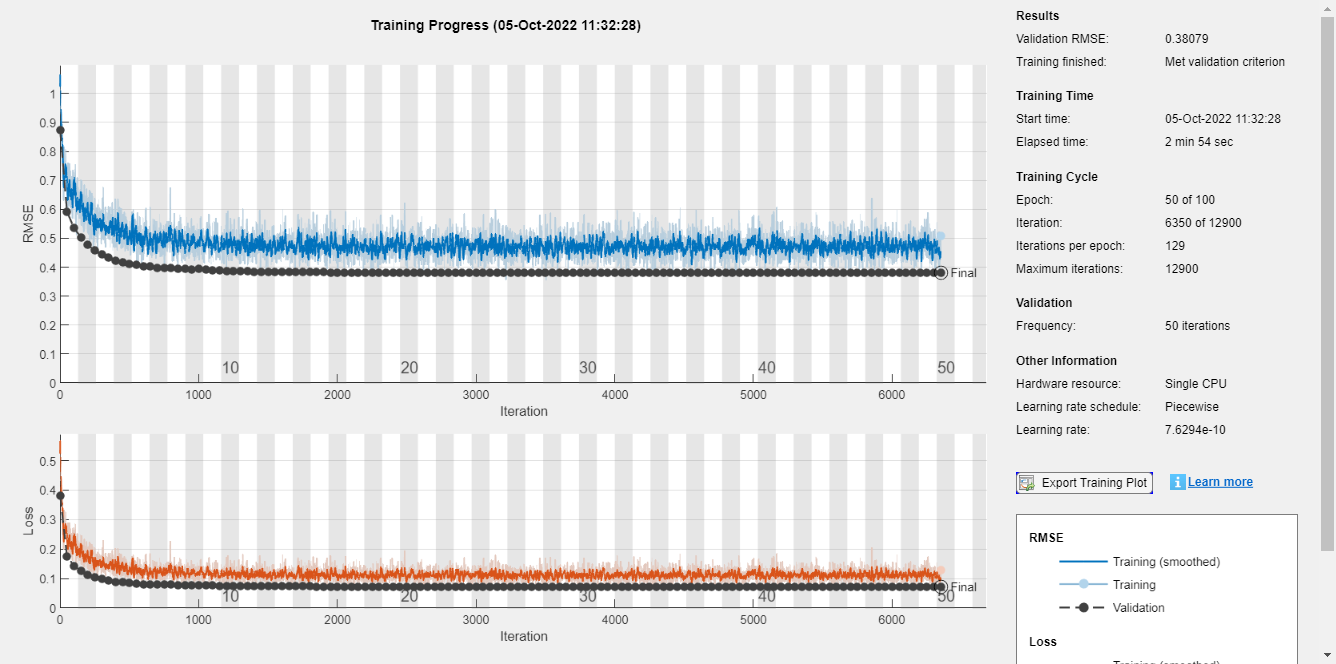

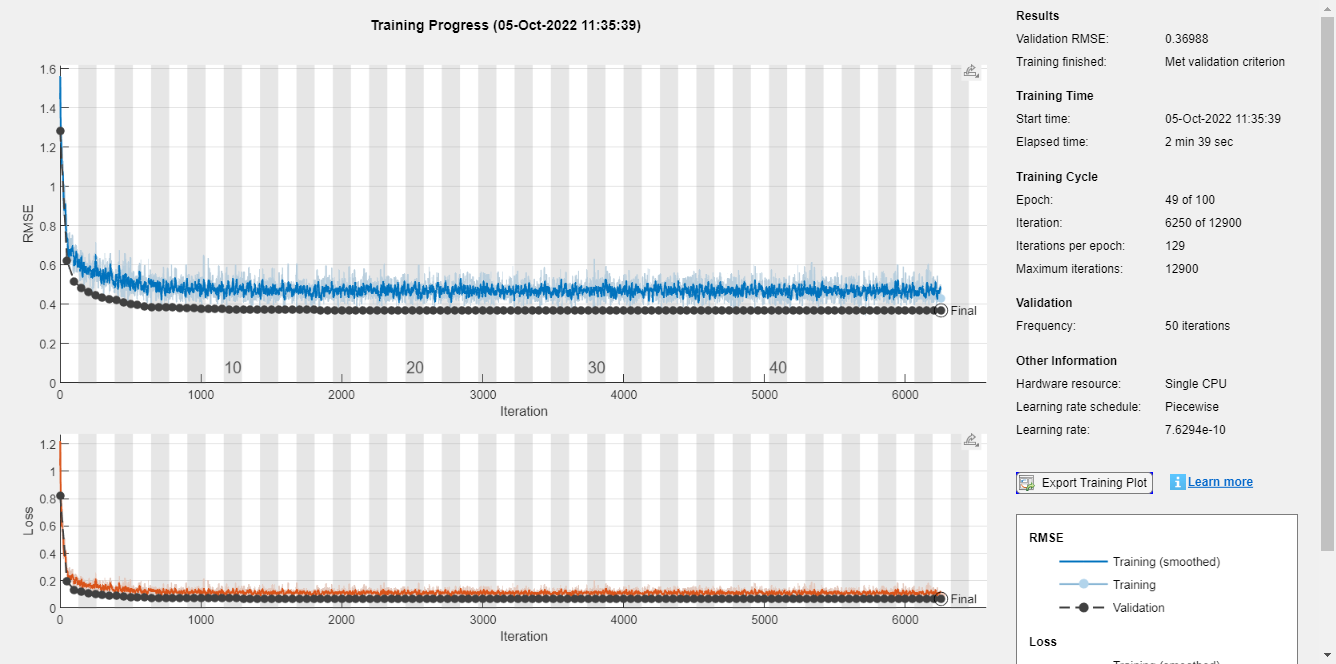

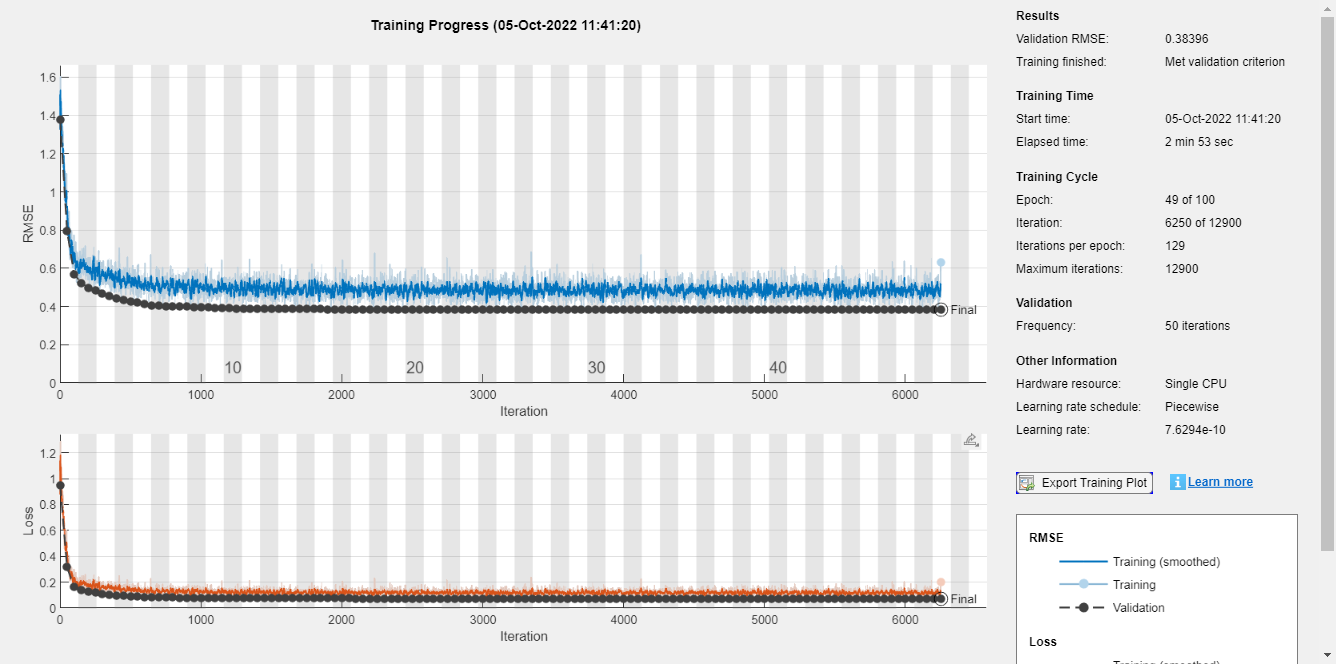

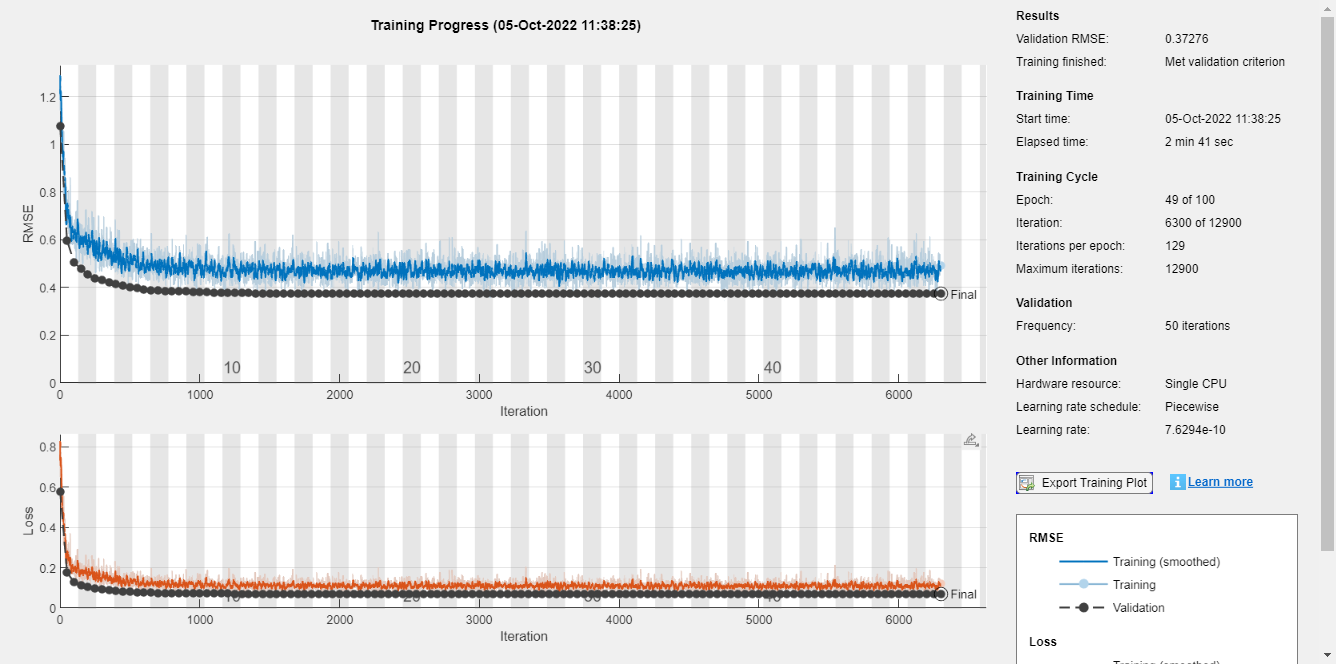

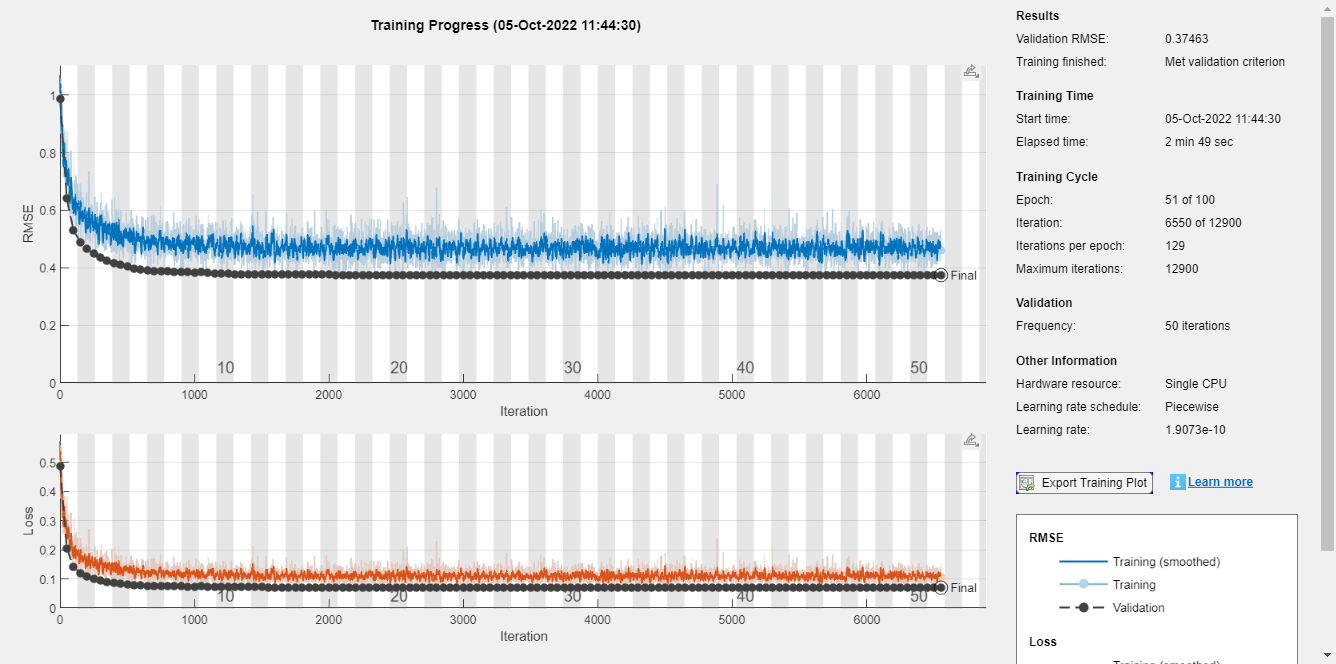

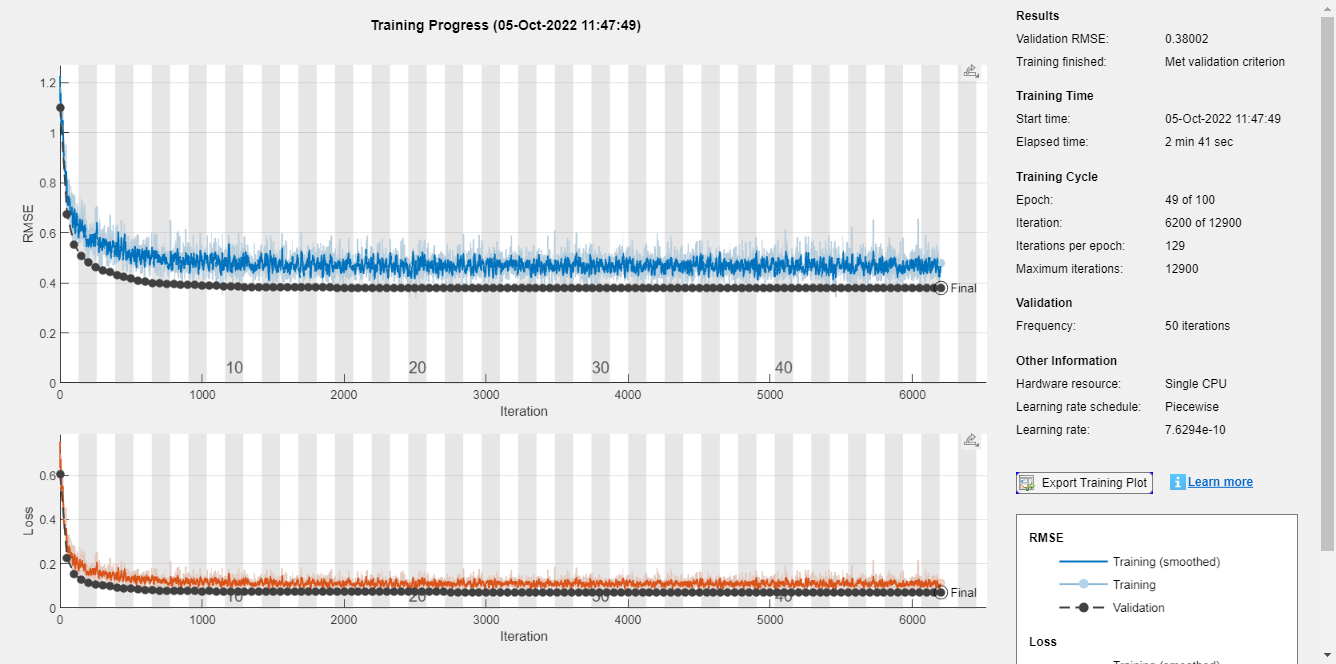

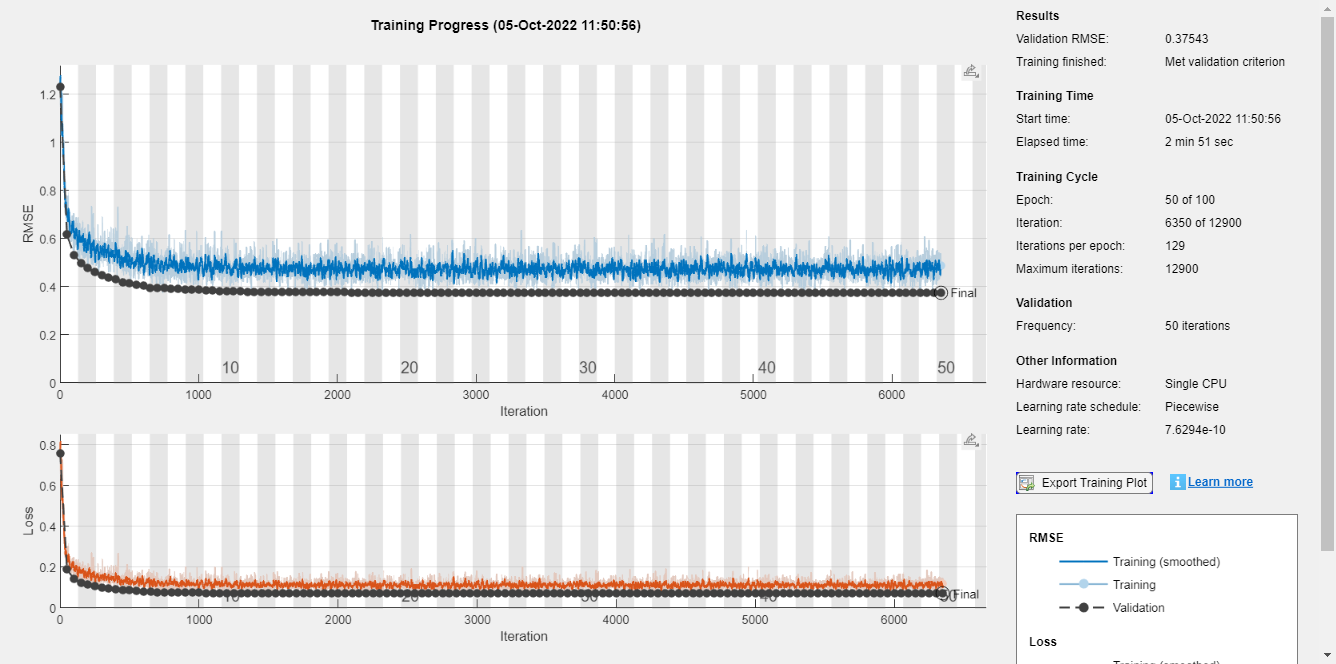

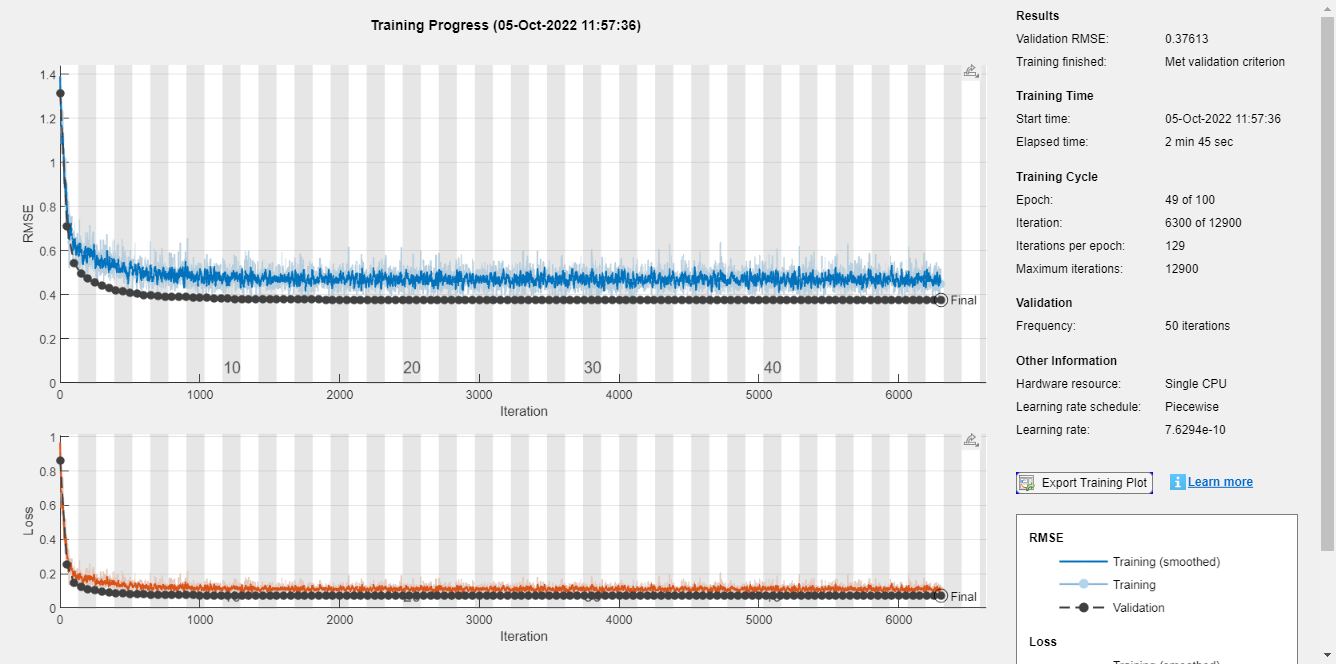

% remove the comment below for Reapitibility
if ripeti==1
time=data.time;
clear data
end

    if flag.WaveletTrasf==0
    
    net = trainNetwork(TrainX(indici_imm.start_riga:indici_imm.end_riga,indici_imm.start_colonna:indici_imm.end_colonna,:,:),TrainY(:,1),layers,options);
    
    else
    layers=CNN_RNN([32 44 3],numResponses);    
    net=trainNetwork(TrainX(:,:,:,1:size(Out1.ca,1)),Out1.ca,layers,options);
    Previsioni1.ca = predict(net,TestY);
    
    net1=trainNetwork(TrainX(:,:,:,1:size(Out1.cd{1,1},1)),Out1.cd{1,1},layers,options);
    Previsioni1cd{1,1} = predict(TestY);
    
    Hs1_ca=ilwt(Previsioni1.ca,Previsioni1cd)
    
    layers=CNN_RNN([16 22 3],numResponses);    
    net2=trainNetwork(TrainX(:,:,:,1:size(Out.cd{1,1},1)),Out.cd{1,1},layers,options);
    Previsionicd{1,1} = predict(net2,TestX);
    
    PrevisioniTest=ilwt(Hs1_ca(1:10360),Previsionicd);
    end

## Previsione della rete in train e test


 if flag.WaveletTrasf==0
 PrevisioniTest = predict(net,TestX(indici_imm.start_riga:indici_imm.end_riga,indici_imm.start_colonna:indici_imm.end_colonna,:,:));
 PrevisioniTrain = predict(net,TrainX(indici_imm.start_riga:indici_imm.end_riga,indici_imm.start_colonna:indici_imm.end_colonna,:,1:length(TrainY_originale(:,1))));
 
 if flag.piu_prove~=0  && (ripeti~=1 && ripeti<10)
 clear net
 clear layers
 clear options
 end

 else
    % PrevisioniTest1 = predict(net,TestX);
    % PrevisioniTest2 = predict(net1,TestX);
    %PrevisioniTest=(PrevisioniTest2+PrevisioniTest1)./2;
 end

    

## Calcolo Parametri di prestazione

[Parametri{ripeti,1}.rho,Parametri{ripeti,1}.pval] = corr(PrevisioniTest(:,1),TestY(:,1));
Parametri{ripeti,1}.accuratezza = sum(round(TestY(:,1), 2,"significant") == round(PrevisioniTest(:,1),2,"significant"),'all')/numel(PrevisioniTest(:,1));
Parametri{ripeti,1}.rmse = sqrt(mean((TestY(:,1) - PrevisioniTest(:,1)).^2));
Parametri{ripeti,1}.mseTRAIN = mse(TrainY_originale(:,1),PrevisioniTrain(:,1))-sqrt(2)+sqrt(2);
Parametri{ripeti,1}.mseTEST = mse(TestY(:,1),PrevisioniTest(:,1))-sqrt(2)+sqrt(2);
% sMAPE calculation
Parametri{ripeti,1}.sMAPE = 0.5*mean(abs(PrevisioniTest(:,1)-TestY(:,1))./(abs(PrevisioniTest(:,1))+abs(TestY(:,1))));
Parametri{ripeti,1}.corrcoefTEST=corrcoef(TestY(:,1),PrevisioniTest(:,1));
Parametri{ripeti,1}.corrcoefTRAIN=corrcoef(TrainY_originale(:,1),PrevisioniTrain(:,1));

%parametri riferiti all'articolo
Parametri{ripeti,1}.Ns=1-(sum((PrevisioniTest-TestY(:,1)).^2)/sum((TestY(:,1)-mean(TestY(:,1))).^2));
Parametri{ripeti,1}.bias= mean(PrevisioniTest)-mean(TestY(:,1));
Parametri{ripeti,1}.Ns_train=1-(sum((PrevisioniTrain-TrainY_originale(:,1)).^2)/sum((TrainY_originale(:,1)-mean(TrainY_originale(:,1))).^2));
Parametri{ripeti,1}.bias_train= mean(PrevisioniTrain)-mean(TrainY_originale(:,1));

[peak_value_test, peak_location_test] = findpeaks(TestY(:,1),'MinPeakHeight',H0,'MinPeakDistance',12);

if flag.growing~=1
[peak_value_train, peak_location_train] = findpeaks(TrainY(:,1),'MinPeakHeight',H0,'MinPeakDistance',12);
end


for i=1:length(peak_value_test)
P(i)=max(PrevisioniTest(peak_location_test(i)-Window_peaks:peak_location_test(i)+Window_peaks));
end

Parametri{ripeti,1}.PRME=sum((P'-TestY(peak_location_test,1))./TestY(peak_location_test,1))/length(P);
Parametri{ripeti,1}.PMARE=sum(abs(P'-TestY(peak_location_test,1))./TestY(peak_location_test,1))/length(P);
Parametri{ripeti,1}.PRMSE=sqrt(sum((P'-TestY(peak_location_test,1)).^2)./size(TestY(peak_location_test,1),1));

for i=1:length(peak_value_train)
P_train(i)=max(PrevisioniTrain(peak_location_train(i)-Window_peaks:peak_location_train(i)+Window_peaks));
end
Parametri{ripeti,1}.PRME_train=sum((P_train'-TrainY_originale(peak_location_train,1))./TrainY(peak_location_train,1))/length(P_train);
Parametri{ripeti,1}.PMARE_train=sum(abs(P_train'-TrainY_originale(peak_location_train,1))./TrainY(peak_location_train,1))/length(P_train);
Parametri{ripeti,1}.PRMSE_train=sqrt(sum((P_train'-TrainY_originale(peak_location_train,1)).^2)./size(TrainY(peak_location_train,1),1));


[Parametri{ripeti,1}.auc_Test,outxTest,outyTest]=fucnt_AUC(PrevisioniTest,TestY(:,1));

fpr =     0.9697    0.3426    0.1735    0.1224    0.0833    0.0660    0.0521    0.0487    0.0374    0.0238


tpr =     0.9933    0.8400    0.7573    0.8056    0.7617    0.7692    0.8372    0.8599    0.8889    1.0000


auc = 0.8726

fpr =     1.0000    0.3163    0.1685    0.1192    0.0879    0.0669    0.0536    0.0457    0.0347    0.0248


tpr =     0.9932    0.8466    0.7642    0.8058    0.7613    0.7842    0.8336    0.8649    0.9394    1.0000


auc = 0.8768

fpr =     0.9688    0.3175    0.1605    0.1166    0.0802    0.0644    0.0517    0.0467    0.0373    0.0253


tpr =     0.9933    0.8435    0.7575    0.7943    0.7584    0.7873    0.8336    0.8559    0.9701    1.0000


auc = 0.8770

fpr =     0.8182    0.3398    0.1633    0.1187    0.0877    0.0637    0.0541    0.0552    0.0405


tpr =     0.9938    0.8333    0.7688    0.8023    0.7437    0.7623    0.8336    0.8850    0.9688


auc = 0.8767

fpr =     0.9024    0.3249    0.1695    0.1215    0.0813    0.0646    0.0501    0.0452    0.0347


tpr =     0.9936    0.8451    0.7627    0.8057    0.7684    0.7703    0.8222    0.8575    0.9588


auc = 0.8771

fpr =     1.0000    0.3560    0.1625    0.1202    0.0831    0.0707    0.0513    0.0472    0.0356    0.0253


tpr =     0.9932    0.8429    0.7623    0.8003    0.7590    0.7749    0.8130    0.8689    0.9651    1.0000


auc = 0.8703

fpr =     1.0000    0.2712    0.1612    0.1201    0.0882    0.0696    0.0512    0.0452    0.0353    0.0249


tpr =     0.9932    0.8435    0.7671    0.8009    0.7516    0.7771    0.8239    0.8365    0.8969    1.0000


auc = 0.8797

fpr =     0.9545    0.2973    0.1720    0.1232    0.0824    0.0633    0.0511    0.0508    0.0380    0.0246


tpr =     0.9933    0.8507    0.7655    0.7878    0.7441    0.7718    0.8552    0.8407    0.9206    1.0000


auc = 0.8828

fpr =     1.0000    0.3202    0.1763    0.1204    0.0850    0.0661    0.0518    0.0498    0.0362    0.0241


tpr =     0.9932    0.8414    0.7771    0.7969    0.7438    0.7606    0.8300    0.8355    0.9059    0.9333


auc = 0.8728

fpr =     1.0000    0.3413    0.1618    0.1163    0.0818    0.0686    0.0492    0.0475    0.0357    0.0245


tpr =     0.9932    0.8419    0.7725    0.8060    0.7560    0.7954    0.8554    0.8498    0.8913    1.0000


auc = 0.8729

[Parametri{ripeti,1}.auc_Train,outxTrain,outyTrain]=fucnt_AUC(PrevisioniTrain,TrainY_originale(:,1));

fpr =     0.8978    0.3210    0.1623    0.1381    0.0906    0.0749    0.0588    0.0433    0.0339    0.0244    0.0154


tpr =     0.9898    0.8154    0.7733    0.8011    0.7702    0.7918    0.7659    0.8277    0.8076    0.8814    1.0000


auc = 0.8738

fpr =     0.9432    0.3182    0.1616    0.1340    0.0910    0.0746    0.0581    0.0421    0.0336    0.0245


tpr =     0.9895    0.8244    0.7844    0.8066    0.7777    0.7849    0.7517    0.7877    0.8051    0.9423


auc = 0.8694

fpr =     0.9659    0.3047    0.1560    0.1349    0.0884    0.0750    0.0576    0.0432    0.0343    0.0251


tpr =     0.9894    0.8224    0.7797    0.7995    0.7826    0.7826    0.7538    0.8284    0.8424    0.9630


auc = 0.8685

fpr =     0.9778    0.3140    0.1614    0.1385    0.0915    0.0794    0.0616    0.0491    0.0391


tpr =     0.9894    0.8118    0.7788    0.8011    0.7573    0.7605    0.7519    0.8283    0.8151


auc = 0.8526

fpr =     0.9429    0.3028    0.1637    0.1329    0.0893    0.0762    0.0577    0.0409    0.0330    0.0256


tpr =     0.9895    0.8239    0.7810    0.8138    0.7710    0.7831    0.7394    0.8163    0.8053    1.0000


auc = 0.8711

fpr =     0.8556    0.3336    0.1585    0.1337    0.0861    0.0789    0.0586    0.0428    0.0333    0.0248


tpr =     0.9897    0.8219    0.7760    0.8086    0.7766    0.7811    0.7504    0.8153    0.8457    1.0000


auc = 0.8754

fpr =     0.8452    0.2779    0.1555    0.1362    0.0933    0.0796    0.0599    0.0415    0.0326    0.0246


tpr =     0.9897    0.8224    0.7831    0.8051    0.7781    0.7875    0.7480    0.8032    0.8025    0.8462


auc = 0.8798

fpr =     0.9070    0.3136    0.1602    0.1311    0.0835    0.0695    0.0557    0.0440    0.0347    0.0244


tpr =     0.9895    0.8246    0.7851    0.8051    0.7618    0.7831    0.7868    0.8483    0.8401    0.8947


auc = 0.8736

fpr =     0.9388    0.3237    0.1644    0.1363    0.0882    0.0734    0.0581    0.0447    0.0347    0.0242


tpr =     0.9895    0.8173    0.7816    0.8061    0.7683    0.7824    0.7563    0.8149    0.7880    0.8333


auc = 0.8645

fpr =     0.9630    0.3136    0.1552    0.1337    0.0875    0.0752    0.0565    0.0424    0.0337    0.0244


tpr =     0.9894    0.8204    0.7880    0.8045    0.7757    0.7838    0.7690    0.8205    0.8208    0.9123


auc = 0.8671


end


if flag.save_net==0
 clear net
 clear layers
 clear options
end

clearvars('TrainX')
clearvars('TestX')
clearvars('ValidationX')
clearvars('anno')
clearvars('colonna')
clearvars('colonna1')
clearvars('end_prove')
clearvars('riga')
clearvars('riga1')
clearvars('ripeti')